# Modifying Squishy Data Processing

Things we want to include:

- one matrix for all our data

- should combine with CaSO4_mixing file

- make this one big function file

Chopping off the outlier data

good_rows = 1:18000;
conductivity_list = conductivity_list(good_rows,:);
permeate_flowrate_list = permeate_flowrate_list(good_rows,:);
flowrate_list = flowrate_list(good_rows,:);
time_list = time_list(good_rows,:);

a/ Calculating salt rejection  = [1-(permeate conductivity)/(average conductivity on feed side of membrane)]

perm_conductivity = 0.1; % mS/c - it's ok to guess
salt_rej = (1-(perm_conductivity)/mean(conductivity_list))*100 % percentage

salt_rej = 98.0944

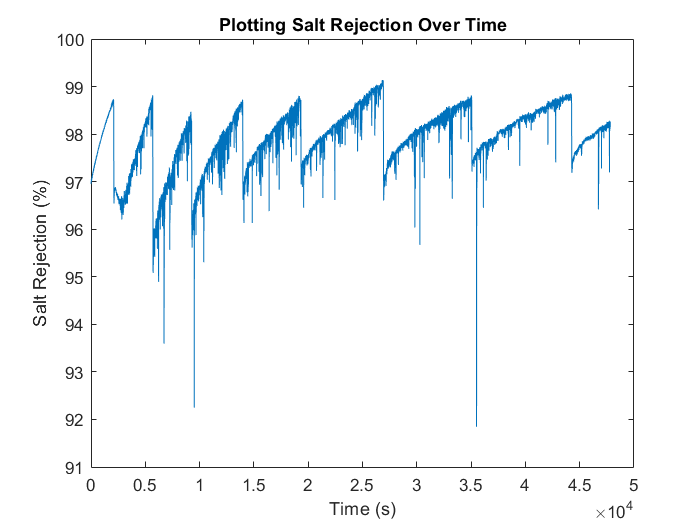

salt_rej_list = (1-(perm_conductivity)./conductivity_list)*100;

plot(time_list,salt_rej_list)
title('Plotting Salt Rejection Over Time')
xlabel('Time (s)')
ylabel('Salt Rejection (%)')

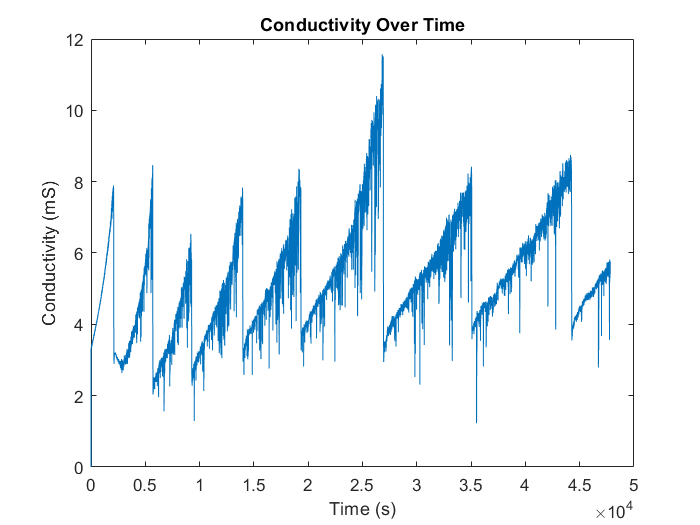


plot(time_list,conductivity_list)
title('Conductivity Over Time')
xlabel('Time (s)')
ylabel('Conductivity (mS)')

b/ Calculate the calcium sulfate concentration at the membrane at each timestep (from input initial concentration and instantaneous recovery and including concentration polarization.)

initial_conc = 626.2;    % intial concentration mg/L
mem_const = 0.99;  % membrane constant (K) 

% recovery should be going up and maybe zero at each cycle
recovery = (sum(permeate_flowrate_list.*time_list))./(flowrate_list.*time_list);  %expressed in terms of a decimal


time_list_min = time_list/60;
perm_ml = permeate_flowrate_list .* time_list_min;
total_perm = sum(perm_ml)

total_perm = 5.0282e+07

feed_ml = flowrate_list .* time_list_min;
total_feed = sum(feed_ml)

total_feed = 3.3635e+09

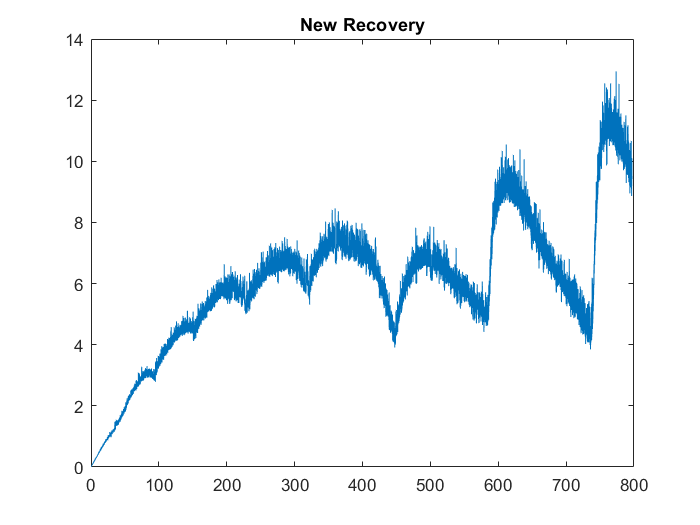


recovery_new = (perm_ml./flowrate_list); %this dont seem right

plot(time_list_min,recovery_new)
title('New Recovery')


recovery_once = total_perm/total_feed

recovery_once = 0.0149

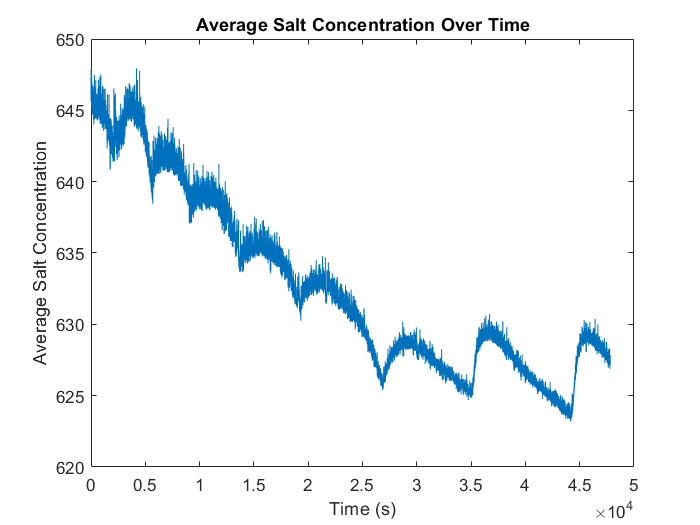


mem_CaSO4_conc = (1./(1-recovery)) .* initial_conc;          % membrane CaSO4 concentration
% what is the difference between conductivity and concentration
conc_polar = mem_const * exp(permeate_flowrate_list./mean(flowrate_list)); % concentration polarization
conc_polar_factor = mem_const * exp(permeate_flowrate_list./flowrate_list);
avg_TDS = conc_polar_factor * initial_conc; % mM/L


%plotting 
plot(time_list,avg_TDS)
title('Average Salt Concentration Over Time')
xlabel('Time (s)')
ylabel('Average Salt Concentration')

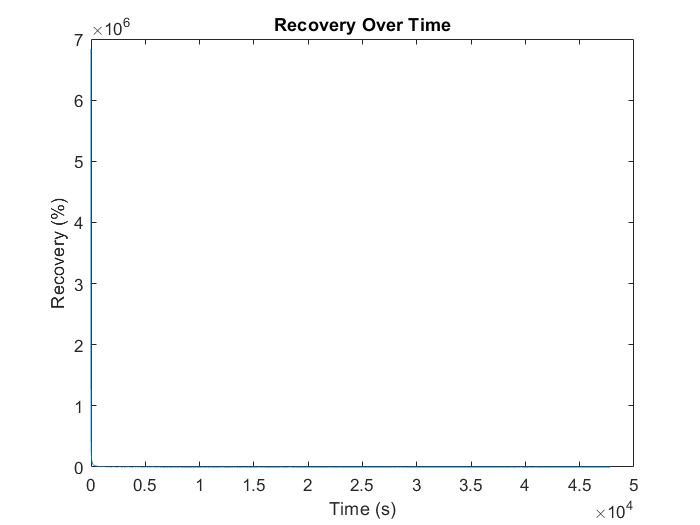


%plotting recovery
plot(time_list,recovery)
title('Recovery Over Time')
xlabel('Time (s)')
ylabel('Recovery (%)')

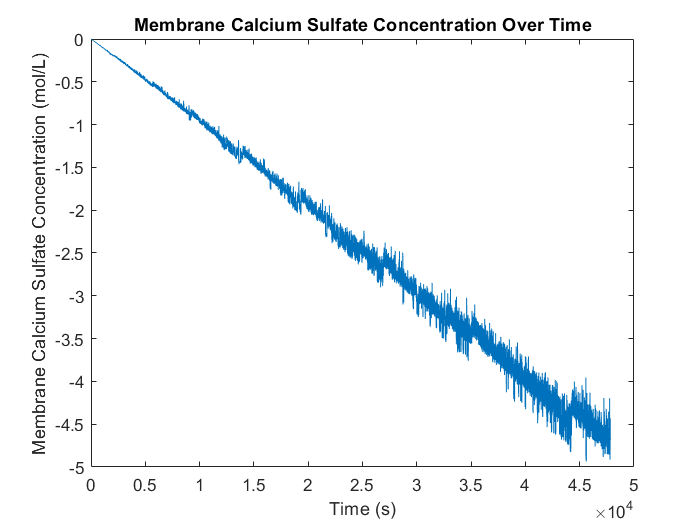


%plotting Membrane Calcium Sulfate Concentration
plot(time_list,mem_CaSO4_conc)
title('Membrane Calcium Sulfate Concentration Over Time')
xlabel('Time (s)')
ylabel('Membrane Calcium Sulfate Concentration (mol/L)')

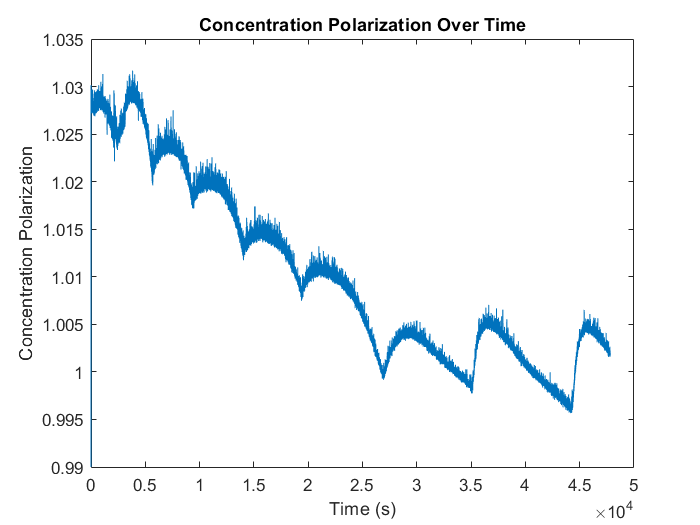


%plotting Concentration Polarization
plot(time_list,conc_polar)
title('Concentration Polarization Over Time')
xlabel('Time (s)')
ylabel('Concentration Polarization')


% plot()
% title('')
% xlabel('')
% ylabel('')

c/ Calculate the saturation index of gypsum (a.k.a. calcium sulfate dihydrate) at the membrane at each timestep.

% equation in comments of doc
sat_index = 0.527 .* log(mem_CaSO4_conc) - 1.5073;

% plotting Saturation Gypsum over time
plot(time_list,sat_index)

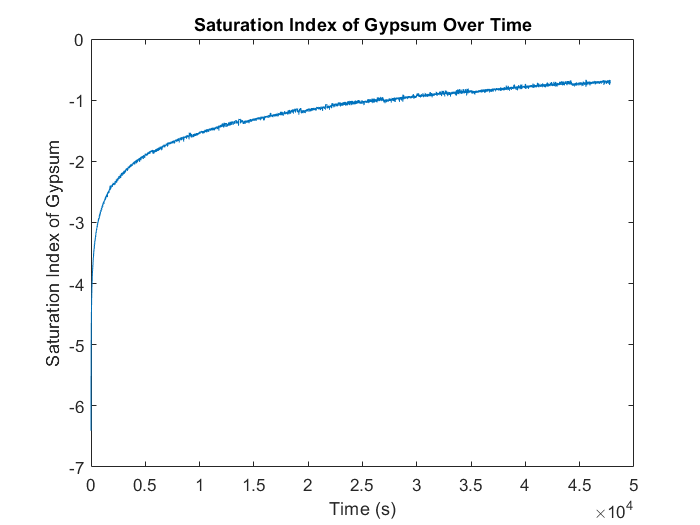

title('Saturation Index of Gypsum Over Time')
xlabel('Time (s)')
ylabel('Saturation Index of Gypsum')

d/ Calculate the nucleation induction time of gypsum at each timestep.

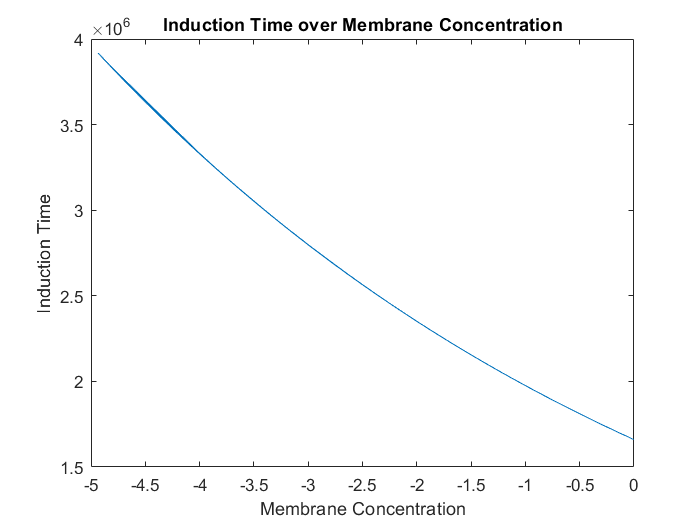

% ---------------------- hmmmmmmmmmmm need to figure out which graph is
% right
conc_over_time = mem_CaSO4_conc ./ time_list; % Membrance Concentration over Time (need to find out units)
ind_time = 1.66*(10^6).*(exp(-0.174.*mem_CaSO4_conc)); % Induction Time in seconds (s)
inv_ind_time = 1./ind_time;

plot(mem_CaSO4_conc,ind_time)
title('Induction Time over Membrane Concentration')
xlabel('Membrane Concentration')
ylabel('Induction Time')

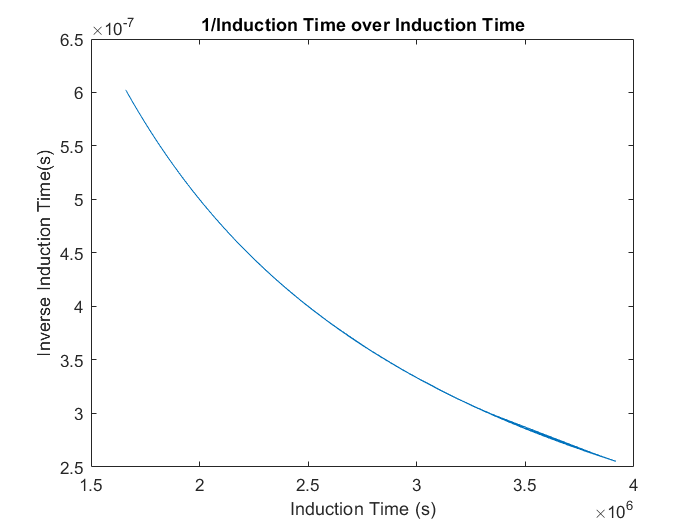


%plotting Induction Time over Time  hmmmmmmmmmm
plot(ind_time,inv_ind_time)
title('1/Induction Time over Induction Time')
xlabel('Induction Time (s)')
ylabel('Inverse Induction Time(s)')

e/ Integrate the induction rate (i.e., the inverse of induction time) over all timesteps in each batch cycle to determine the nucleation probability per cycle

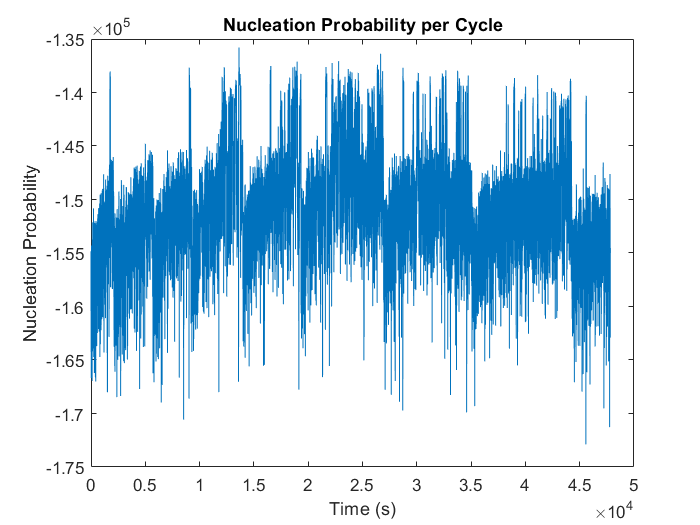

timestep = time_list(1:10:length(time_list));

nuc_prob = (log(ind_time)./conc_over_time);

plot(time_list,nuc_prob)
title('Nucleation Probability per Cycle')
xlabel('Time (s)')
ylabel('Nucleation Probability')


% 1/induction over induction time
% rate is the probability happening in each second and do that times a time
% step and then if you add that rate * time steps it should give you the
% nucleation probability